# **demo03 of writeMesh**

**Quadrilateral mesh**

Cite as: Ma, J., & Li, Y. (2025). Im2mesh: A MATLAB/Octave package for generating finite element mesh based on 2D multi-phase image (2.1.5). Zenodo. [https://doi.org/10.5281/zenodo.14847059](https://doi.org/10.5281/zenodo.14847059)

Jiexian Ma, mjx0799@gmail.com. [Project website](https://github.com/mjx888/writeMesh).

## Initialize

clearvars

Set default image size.

x = 250; y = 250; width = 250; height = 250;
set(groot, 'DefaultFigurePosition', [x,y,width,height])
% To reset:
% set(groot, 'DefaultFigurePosition', 'factory')

## Load mesh

Let's load the mesh data from "mesh_data_3.mat"

load("mesh_data_3.mat")

We will see 3 variables: vert, ele, tnum

vert

vert =     4.6900   23.8200
    4.8300   25.9900
    5.4000   51.5200
    5.8100   21.8900
    5.8400   55.1300
    6.1100   48.1200
    6.1500   27.8100
    8.4500   19.4400
   10.4000   63.5800
   10.9200   17.9300


ele

ele =    207   217   220   219
   214   218   220   217
   216   219   220   218
   200   221   224   223
   183   222   224   221
   212   223   224   222
   204   225   228   227
   208   226   228   225
   214   227   228   226
   190   229   232   231


tnum

tnum =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


Check the number of phase in the mesh

length(unique(tnum))

ans = 3

## Plot mesh

Use function plotMeshes to plot mesh.

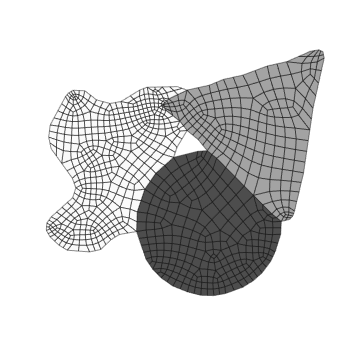

plotMeshes(vert,ele,tnum);

We saw 3 phases in the mesh.

## Export as inp file (Abaqus)

We use function printInp2d to write 2d mesh to inp file.

The exported inp file would have a model with one part, which contains 3 sections. Each section corresponds to one phase in the mesh.

We can specify element type, precision and file name.

ele_type = 'CPS4';
precision = 8;
file_name = 'test.inp';

printInp2d( vert, ele, tnum, ele_type, precision, file_name );

printInp2d Done! Check the inp file!


## Export as bdf file (Nastran bulk data)

We use function printBdf2d to write 2d mesh to bdf file.

precision = 8;
file_name = 'test.bdf';

printBdf2d( vert, ele, tnum, [], precision, file_name );

printBdf2d Done! Check the bdf file!


## Export as msh file (Gmsh mesh file)

Function printMsh currently does not work for quadrilateral element. We will see error message.

% reset image size
set(groot, 'DefaultFigurePosition', 'factory')

% end of demo